# Linear Control Design II - Group Work Problem Module 13

## Description

This group work module deals with the design of a full state feedback controller for the model of the aircraft analysed in Group Work Module 7 (the SISO model).

% Define system matrices:
A = [-0.0558 -0.9968  0.0802  0.0415;
      0.598  -0.115  -0.0318  0;
     -3.050   0.388  -0.4650  0;
      0       0.0805  1       0]

A =    -0.0558   -0.9968    0.0802    0.0415
    0.5980   -0.1150   -0.0318         0
   -3.0500    0.3880   -0.4650         0
         0    0.0805    1.0000         0


B = [0.00729; -0.475; 0.153; 0]

B =     0.0073
   -0.4750
    0.1530
         0


C = [0 1 0 0]

C =      0     1     0     0


D = 0;

**Problem 1**

Transform the continuous time model given in Module 7 into the controller canonical form.


$$P_{ch,\lambda}=\lambda^n+a_{n-1}\lambda^{n-1}...+a_1\lambda+a_0\\
P_1=B\\
P_2=AP_1+a_{n-1}P_1\\
P_3 =AP_2+a_{n-2}P_1\\
...\\
P=[P_n \ P_{n-1} \ ... \ P_1]\\

$$



$$A_{cc} =P^{-1}AP\\
B_{cc}=P^{-1}B\\
C_{cc} = CP\\
D_{cc}=D$$


% Your solution goes here:
% origin eigen value
eig(A)

ans =   -0.0329 + 0.9467i
  -0.0329 - 0.9467i
  -0.5627 + 0.0000i
  -0.0073 + 0.0000i


chapo = poly(A)

chapo =     1.0000    0.6358    0.9389    0.5116    0.0037


p1 = B;
p2 = A*p1 + chapo(2)*p1;
p3 = A*p2 + chapo(3)*p1;
p4 = A*p3 + chapo(4)*p1;

P = [p4 p3 p2 p1];
Acc = inv(P)*A*P

Acc =    -0.0000    1.0000    0.0000   -0.0000
    0.0000    0.0000    1.0000    0.0000
   -0.0000    0.0000    0.0000    1.0000
   -0.0037   -0.5116   -0.9389   -0.6358


Bcc = inv(P)*B

Bcc =    -0.0000
         0
   -0.0000
    1.0000


Ccc = C*P

Ccc =    -0.0563   -0.1187   -0.2479   -0.4750


Dcc = D

Dcc =      0


**Problem 2**

It is desired to assign the eigenvalues through state feedback such that the damping ratio for the least damped eigenvalues is increased to approximately 0.7, and such that natural frequencies and time constants are approximately unchanged. A reasonable assignment could be:


$$\lambda = \left\{\matrix{-0.01 \cr -0.6 \cr -0.5\pm0.5j} \right.$$


Find the gain matrix K for the controller


$$u = -\textbf{Kx}+r$$


by applying the method from Section 4.3.1 in the textbook. Check that the eigenvalues of the closed-loop system have been assigned as desired.

**Solution:**


$$\dot{z}(t)=A_{CC}z(t)+B_{CC}u(t)\\
u = -K_{CC}z\\
K_{CC} = [k1 \ k2 \ k3 \ k4]\\
 \ =[\alpha_4-a_4 \ \alpha_3-a_3 \ \alpha_2-a_2 \ \alpha_1-a_1 \ \alpha_0-a_0]\\
\dot{z}=A_{K_{CC}}z+B_{CC}r\\
A_{K_{cc}}=A_{CC}-B_{CC}K_{CC}\\
P_{ch,A_{K_{CC}}}=\lambda^4+\alpha_3\lambda^3+\alpha_2\lambda^2+\alpha_1\lambda^1+\alpha_0$$


That is 

- get coefficients of $\alpha$

- get Kcc

- get K

% Your solution goes here:
Mc = ctrb(A,B)

Mc =     0.0073    0.4853   -0.0985   -0.4044
   -0.4750    0.0541    0.2928   -0.0503
    0.1530   -0.2777   -1.3302    1.0327
         0    0.1148   -0.2733   -1.3066


rank(Mc)

ans =      4


alpha = poly([-0.01 -0.6 -0.5+0.5i -0.5-0.5i])

alpha =     1.0000    1.6100    1.1160    0.3110    0.0030


Kcc = fliplr(alpha-chapo)

Kcc =    -0.0007   -0.2006    0.1771    0.9742         0


Kcc = Kcc(1:4)

Kcc =    -0.0007   -0.2006    0.1771    0.9742


K = Kcc*inv(P)

K =    -0.5869   -1.9909    0.2145    0.0862


Check if the eigenvalues of closed-loop system is as desired.

eig(A-B*K)

ans =   -0.0100 + 0.0000i
  -0.5000 + 0.5000i
  -0.5000 - 0.5000i
  -0.6000 + 0.0000i


**Problem 3**

Add the controller to the Simulink open-loop model and carry out a simulation with the function shown on Figure 1 as input to the closed-loop system. Plot the states, the output and the rudder angle.

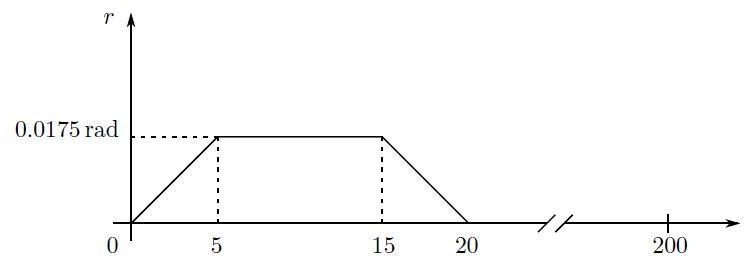


$$Figure\,1: Input\,signal\,to\,the\,closed\,loop\,system.$$


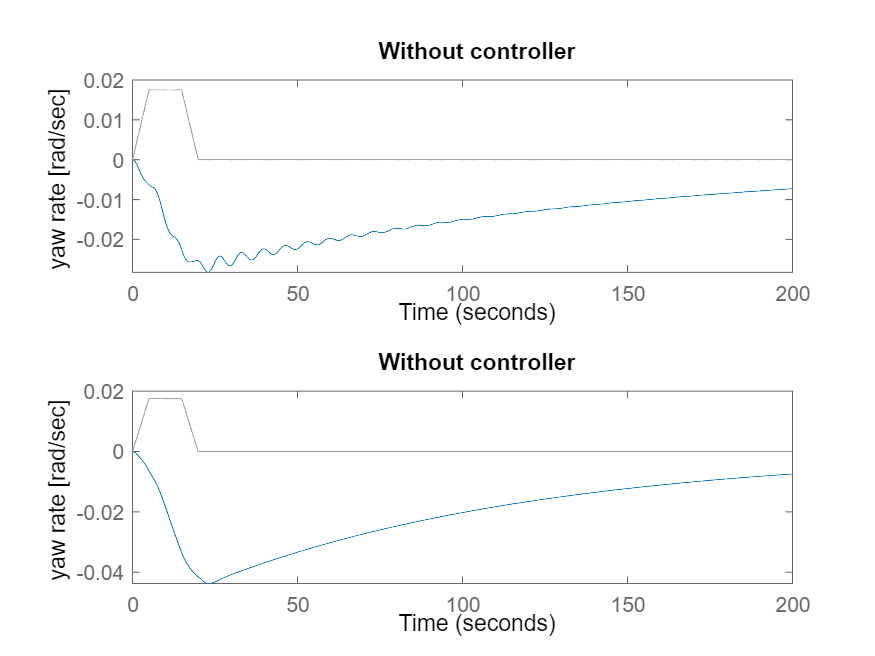

% Your solution goes here:
t = 0:0.1:199.9;
ut1 = (0:50)*0.0175/50;
ut2 = ones(1,98)*0.0175;
ut3 = (0:50)*(-0.0175/50)+0.0175;
ut4 = zeros(1,1800);

u = [ut1 ut2 ut3 ut4];
x0 = [0 0 0 0]';

figure
subplot(2,1,1)
lsim(A,B,C,D,u,t,x0)
title('Without controller');
ylabel('yaw rate [rad/sec]');
subplot(2,1,2)
lsim(A-B*K,B,C,D,u,t,x0)
title('Without controller');
ylabel('yaw rate [rad/sec]');

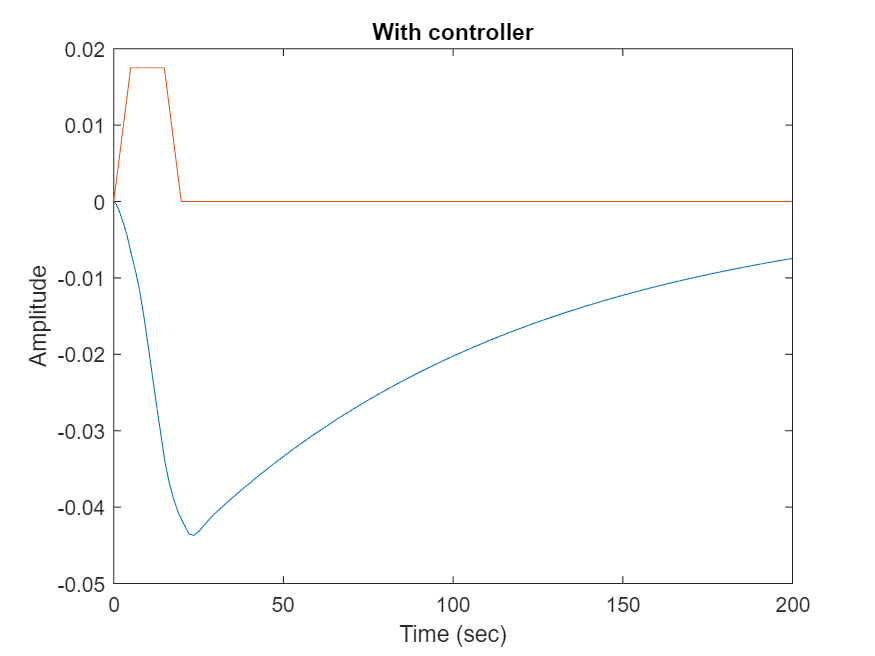

figure
sim('my747controller')
plot(simout.time, simout.signals.values);
hold on
plot(t,u);
title('With controller');
xlabel('Time (sec)');
ylabel('Amplitude');

**Problem 4**

Repeat Problems 2 and 3 with the largest time constant decreased by a factor 50 and by applying Ackermann's formula (the Matlab's function is called *acker()*). The Ackermann's formula has to be applied to the original model.

**Solution:**


$$\lambda = \left\{\matrix{-0.01\cdot 50 \cr -0.6 \cr -0.5\pm0.5j} \right.$$


% Your solution goes here:
eigclose = [-0.01*50 -0.6 -0.5+0.5i -0.5-0.5i];
KQ4 = acker(A,B,eigclose)

KQ4 =     0.4474   -3.0480    0.0860    0.0163


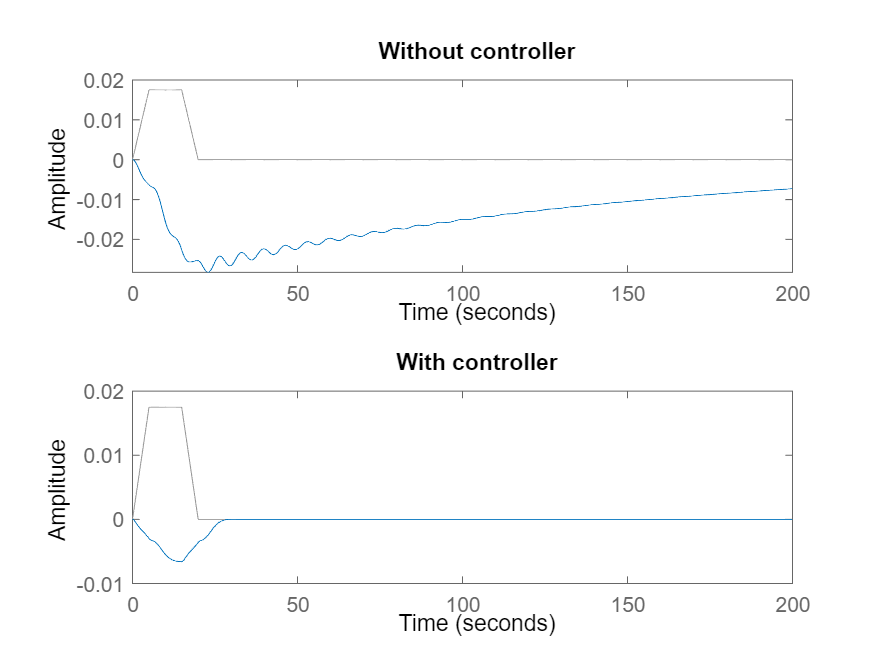

%figure
subplot(2,1,1);
lsim(A,B,C,D,u,t,x0)
title('Without controller');
subplot(2,1,2)
lsim(A-B*KQ4,B,C,D,u,t,x0)
title('With controller')

**Problem 5**

Repeat Problem 4 for a discrete time controller. Do not forget to convert the eigenvalues to the discrete domain. The discrete time controller must be tested together with the continuous time plant. To enable interaction between the continuous and discrete time parts of the control loop do not forget to insert digital-to-analogue (DAC) and analogue-to-digital (ADC) converters into the system. The DAC is usually a zero-order hold, and such a block is available in Simulink's discrete library. The ADC is implemented in Simulink as a discrete transfer function (same library) with 1 as numerator and denominator, as shown in Figure 2. All discrete blocks use the parameter *Sample Time*, which has to be chosen in a suitable manner.

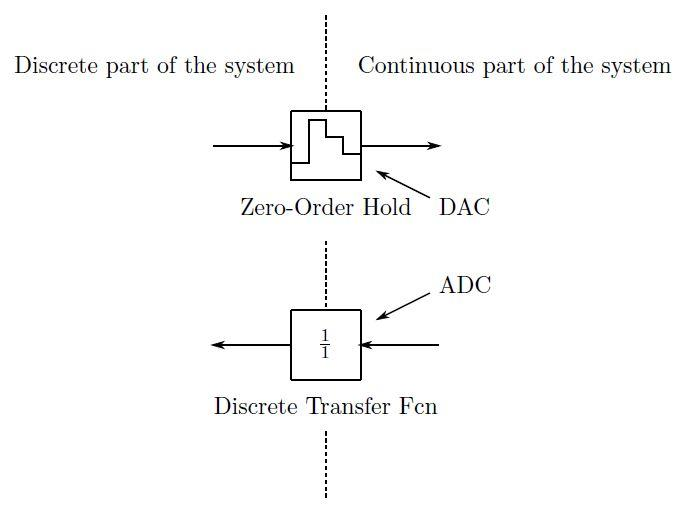


$$Figure\,2:Simulink\,discretization\,blocks.$$


% Your solution goes here:
Ts = 0.1;
F = expm(A*Ts)

F =     0.9902   -0.0985    0.0082    0.0041
    0.0597    0.9855   -0.0028    0.0001
   -0.2956    0.0525    0.9533   -0.0006
   -0.0147    0.0104    0.0977    1.0000


[F,G] = c2d(A,B,Ts)

F =     0.9902   -0.0985    0.0082    0.0041
    0.0597    0.9855   -0.0028    0.0001
   -0.2956    0.0525    0.9533   -0.0006
   -0.0147    0.0104    0.0977    1.0000


G =     0.0031
   -0.0472
    0.0137
    0.0005


sys = ss(F,G,C,D,Ts)

sys =
 
  A = 
              x1         x2         x3         x4
   x1     0.9902   -0.09852   0.008162   0.004133
   x2    0.05968     0.9855  -0.002846   0.000124
   x3    -0.2956    0.05251     0.9533   -0.00062
   x4    -0.0147     0.0104    0.09766          1
 
  B = 
              u1
   x1   0.003138
   x2   -0.04718
   x3    0.01369
   x4  0.0005229
 
  C = 
       x1  x2  x3  x4
   y1   0   1   0   0
 
  D = 
       u1
   y1   0
 
Sample time: 0.1 seconds
Discrete-time state-space model.



% discrete eigenvalues
eigDisc = exp(eigclose*Ts)

eigDisc =    0.9512 + 0.0000i   0.9418 + 0.0000i   0.9500 + 0.0475i   0.9500 - 0.0475i


Kdisc = acker(F,G,eigDisc)

Kdisc =     0.3155   -2.8363    0.0850    0.0159


figure
sim("my747controller_discretization.slx")

No system or file called 'my747controller_discretization.slx' found.

subplot(2,1,1)
lsim(sys,u,t,x0)
title('Without controller');
subplot(2,1,2)
plot(simout.time,simout.signals.values);
hold on
plot(t,u);
hold off;
title('With controller');
% subplot(3,1,3)
% lsim(F-Kdisc*G,G,C,D,u,t,x0)
% title('With Controller by matrix')
xlabel('Time (sec)');
ylabel('Amplitude');

**Problem 6**

Compare the system responses from Problem 4 and 5, and discuss the effect of discretization on the system performance.

% Your solution goes here:

